clc
clear all
%Linear MPC design
%(a)
A=[1.2 1;0 1];
B=[0; 1];
model = LTISystem('A', [1.2 1;0 1], 'B', [0; 1]);% stable A
model.x.min = [-15; -15];
model.x.max = [ 15;  15];
model.u.min = -1;
model.u.max =  1;
X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);
Q=eye(2);
R=100;
N=4;
model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);
%%%%%%%%%%%%%%%%
%Theorom 11.13%
%%%%%%%%%%%%%%%%%%%%%%%%K from LQR
Tset   = Polyhedron([0 0]);
[K,S,e] = dlqr(A,B,Q,R)

K =     0.2041    0.6545


S =    16.0929   32.9899
   32.9899   93.9396


e =    0.7728 + 0.1469i
   0.7728 - 0.1469i


%%%%%%%%%%%%%Pf from dlyap
[K,~,~,~,~] = MPC_batch(A,B,N,Q,R,S)

K =     0.2041    0.6545


X111 = dlyap((A-B*K)',(Q+K'*R*K),[],eye(size(A)))

X111 =    16.0929   32.9899
   32.9899   93.9396


%%%%%%%%%%%%%%%%%%
P = model.LQRPenalty

Quadratic Function: R^2 -> R^1


P.weight

ans =    16.0929   32.9899
   32.9899   93.9396


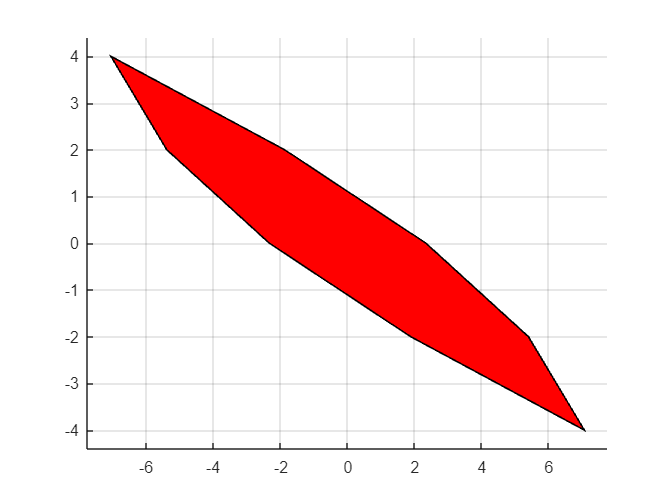


model.x.with('terminalPenalty');
model.x.terminalPenalty = P;

model.x.with('terminalSet');
model.x.terminalSet = Tset;


% Compute the feasible set XN
XN = Tset;
for i = 1:N
    XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward');
    XN = XN.intersect(X).minHRep();
end
plot(XN)

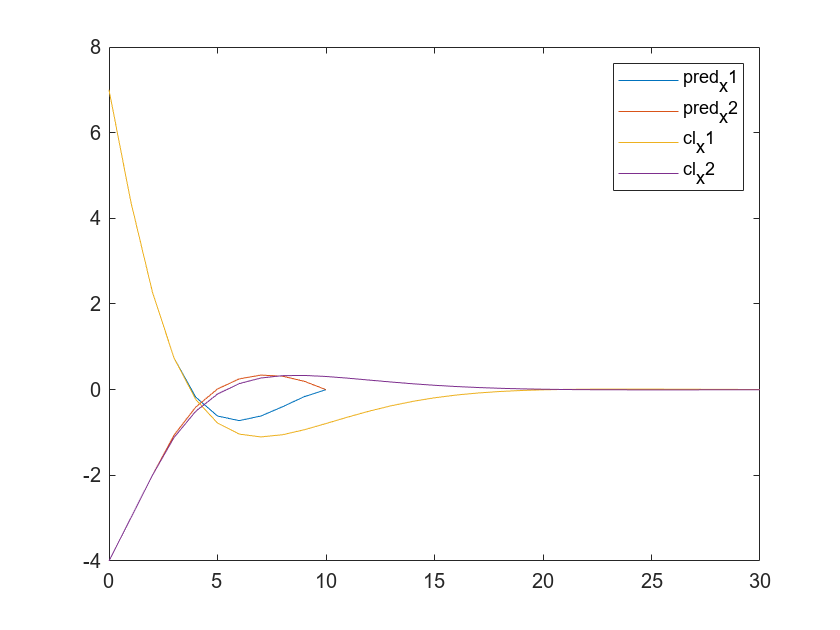

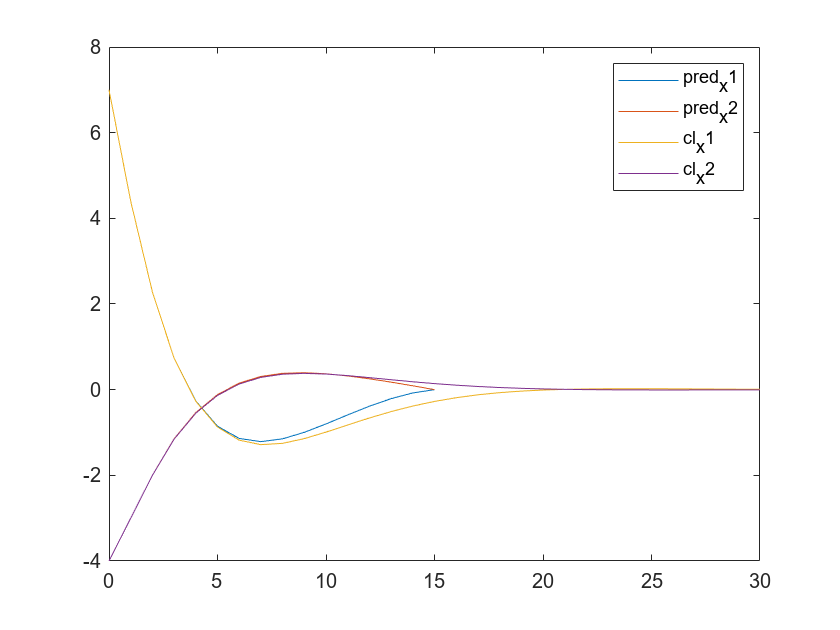

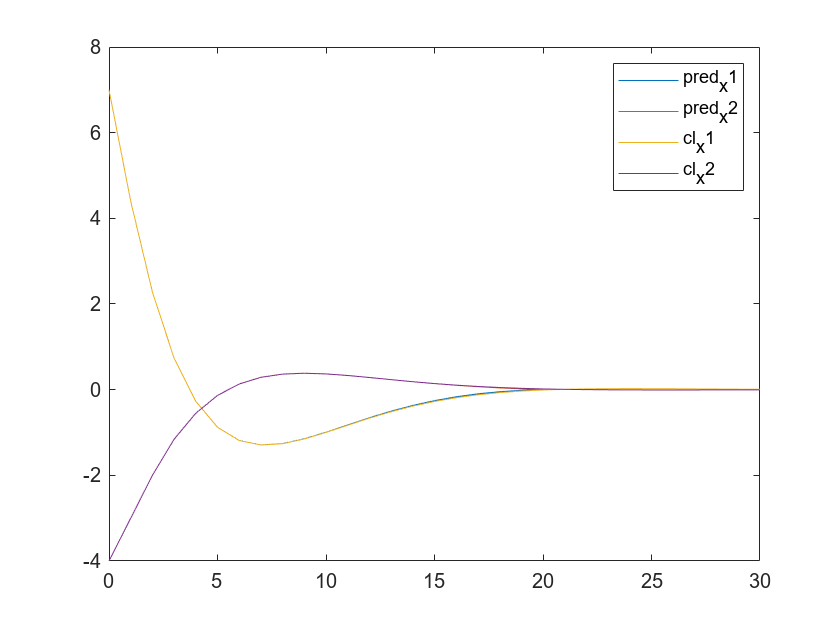

%(b)
N=[10,15,20];
x0=[7;-4];
for i=1:3
    pred=MPCController(model, N(i));
    ctrl = MPCController(model,N(i));
    [~, ~, data1] = pred.evaluate(x0);
    loop = ClosedLoop(ctrl, model);
    Nsim = 30;
    data2 = loop.simulate(x0, Nsim);
    figure()
    plot(0:N(i),data1.X(1,:))
    hold on
    plot(0:N(i),data1.X(2,:))
    hold on
    plot(0:Nsim,data2.X(1,:))
    hold on
    plot(0:Nsim,data2.X(2,:))
    legend('pred_x1','pred_x2','cl_x1','cl_x2')
    hold off
end

%(c)
N=20

N = 20

Tset=Polyhedron('lb', [-0.01;-0.01], 'ub', [0.01;0.01]);
model.x.terminalSet = Tset;
model.x.terminalPenalty = model.LQRPenalty;
mpc = MPCController(model, N);
expmpc = mpc.toExplicit();

mpt_plcp: 71 regions


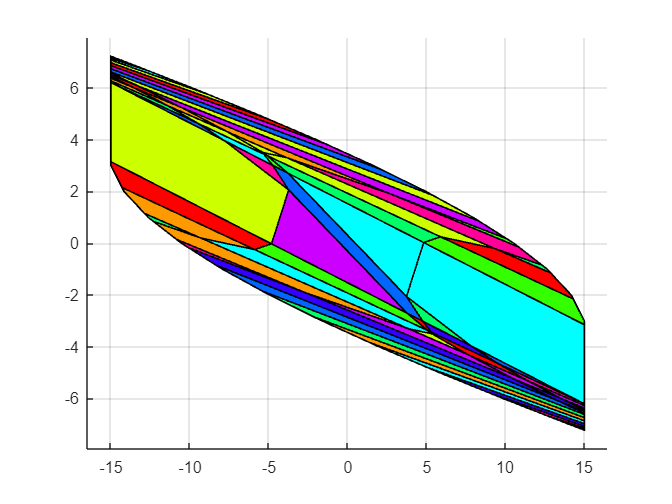

[~, ~, data3] = expmpc.evaluate(x0);
figure()
expmpc.partition.plot()

%(d)
C_inf=model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...


Xf = model.reachableSet('X',C_inf,'U',U,'N',1,'direction','forward')

Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  24 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Xf = Xf.intersect(C_inf);

x01=model.reachableSet('X',Xf,'U',U,'N',1,'direction','backward')

Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  24 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


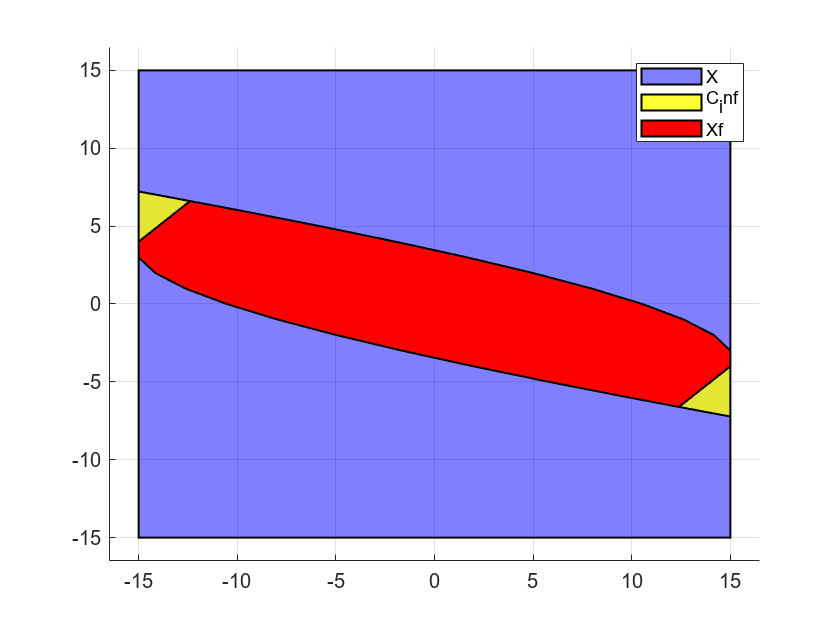

x01= x01.intersect(X).minHRep();

figure()
plot(X,'alpha',0.5,'color','blue',C_inf,'alpha',0.8,'color','yellow',Xf)
legend({'X','C_inf','Xf'})

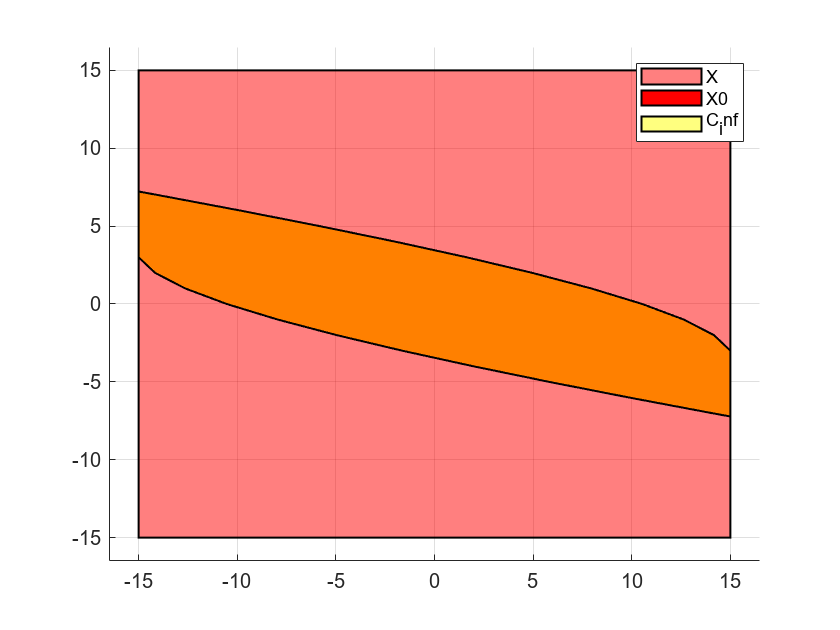


figure()
plot(X,'alpha',0.5,x01,C_inf,'alpha',0.8,'color','yellow','alpha',0.5)
legend({'X','X0','C_inf'})

%2.Finite time control of a DC motor

%(a)
Ls=1;ds=0.02;jm=0.5;bm=0.1;R=20;kt=10;
p=20;k0=1280.2;jl=50*jm;bl=25;
A=[0 1 0 0;-k0/jl -bl/jl k0/(p*jl) 0;0 0 0 1;k0/(p*jm) 0 -k0/(p^2*jm) -(bm+kt^2/R)/jm];
B=[0 0 0 kt/(R*jm)]';
C=[k0 0 -k0/p 0];
D=[0];
sys=ss(A,B,C,D);
h=0.1;
sys_d=c2d(sys,h);
Ad=sys_d.A

Ad =     0.7637    0.0873    0.0118    0.0003
   -4.4281    0.6764    0.2214    0.0086
    0.4444    0.0159    0.9778    0.0621
    7.1286    0.4285   -0.3564    0.3449


Bd=sys_d.B

Bd =     0.0000
    0.0003
    0.0036
    0.0621


%(b)
model = LTISystem('A', sys_d.A, 'B', sys_d.B,'C',C);
Tset = Polyhedron('Ae',[0 1 0 0; 0 0 0 1],'be',[0; 0]);
model.u.min = -200;
model.u.max = 200;
u_c=Polyhedron('lb',model.u.min,'ub',model.u.max);
model.x.with('terminalSet');
model.x.terminalSet = Tset;
xb=[];
ub=[];
yb=[];
x0=[0 2.5 0 75]'

x0 =          0
    2.5000
         0
   75.0000


xN=Tset

Affine set with 2 equations in R^4


k(1)=Tset

Affine set with 2 equations in R^4


N=0

N = 0

% Tset = Polyhedron('Ae',[0 1 0 0; 0 0 0 1],'be',[0; 0]);
while ~Tset.contains(x0)
    N=N+1
    x_pre=model.reachableSet('X',Tset,'U',u_c,'N',1,'direction','backward');
    Tset=x_pre%no constrain here
    k(N+1)=Tset
end

N = 1

Polyhedron in R^4 with representations:
    H-rep (irredundant) : Inequalities   6 | Equalities   1
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 2 polyhedra.


N = 2

Polyhedron in R^4 with representations:
    H-rep (irredundant) : Inequalities  10 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 3 polyhedra.


N = 3

Polyhedron in R^4 with representations:
    H-rep (irredundant) : Inequalities  20 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 4 polyhedra.


x0=[0 2.5 0 75]'

x0 =          0
    2.5000
         0
   75.0000


for i=1:N
    model.x.terminalSet = k(N-i+1);
    [x0,x,u,y] =MPC_Controller(Ad,Bd,model,1,x0);
    disp(i)
    x0
    xb(:,i)=x0
    ub(:,i)=u
end

     1



x0 =     0.2406
    2.2809
    4.0896
   16.6414


xb =     0.2406
    2.2809
    4.0896
   16.6414


ub = -165.9088

     2



x0 =     0.4348
    1.4616
    4.4465
   -5.4360


xb =     0.2406    0.4348
    2.2809    1.4616
    4.0896    4.4465
   16.6414   -5.4360


ub =  -165.9088 -200.0000


     3



x0 =     0.5103
         0
    4.2113
   -0.0000


xb =     0.2406    0.4348    0.5103
    2.2809    1.4616         0
    4.0896    4.4465    4.2113
   16.6414   -5.4360   -0.0000


ub =  -165.9088 -200.0000   -4.2842


xb1=[[0 2.5 0 75]',xb]

xb1 =          0    0.2406    0.4348    0.5103
    2.5000    2.2809    1.4616         0
         0    4.0896    4.4465    4.2113
   75.0000   16.6414   -5.4360   -0.0000


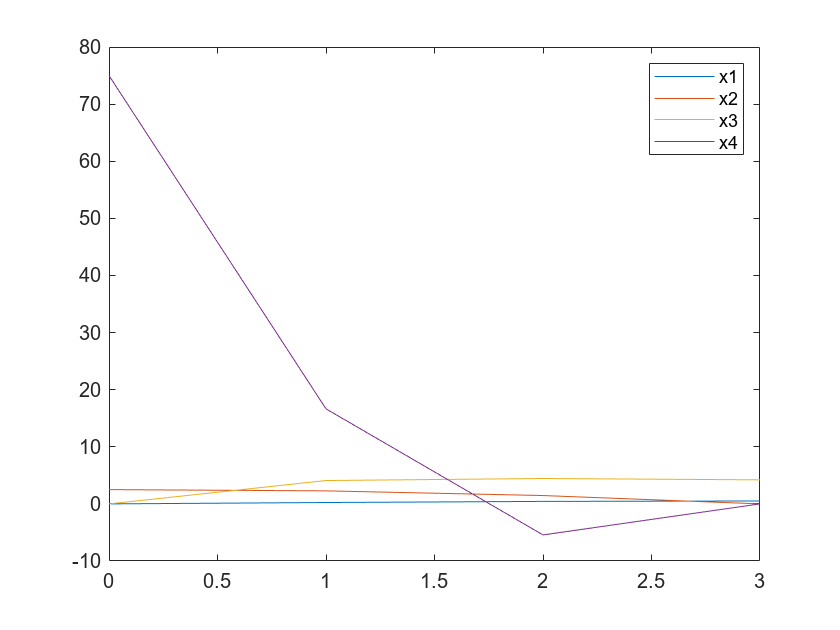

figure()
plot(0:3,xb1(1,:))
hold on 
plot(0:3,xb1(2,:))
hold on 
plot(0:3,xb1(3,:))
hold on 
plot(0:3,xb1(4,:))
hold on 
legend('x1','x2','x3','x4')

y=C*xb1

y =          0   46.2996  271.9514  383.7673


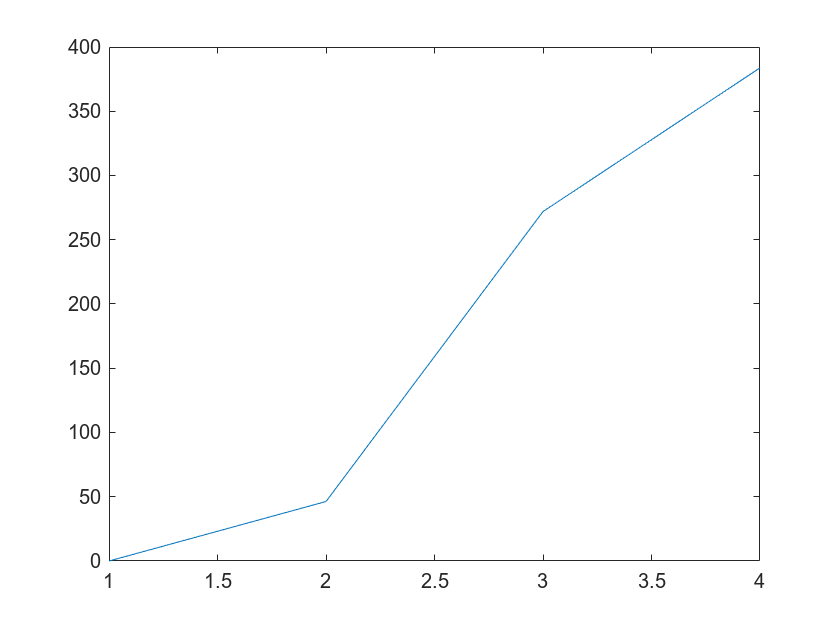

figure()
plot(y)

% %(C)
model = LTISystem('A', sys_d.A, 'B', sys_d.B,'C',C);
Tset = Polyhedron('Ae',[0 1 0 0; 0 0 0 1],'be',[0; 0]);
model.u.min = -200;
model.u.max = 200;
u_c=Polyhedron('lb',model.u.min,'ub',model.u.max);
model.x.with('terminalSet');
model.x.terminalSet = Tset;
X=Polyhedron('A',[C;-C],'b',[150;150]);  
model.x.with('setConstraint');
model.x.setConstraint=X;

% xb=[];
% ub=[];
% yb=[];
x0=[0 2.5 0 75]'

x0 =          0
    2.5000
         0
   75.0000


k(1)=Tset

Array of 9 polyhedra.


N=0

N = 0

Tset = Polyhedron('Ae',[0 1 0 0; 0 0 0 1],'be',[0; 0]);
while ~Tset.contains(x0)
    N=N+1;
    x_pre=model.reachableSet('X',Tset,'U',u_c,'N',1,'direction','backward');
    Tset=x_pre.intersect(X);
    k(N+1)=Tset;
end



x0=[0 2.5 0 75]'

x0 =          0
    2.5000
         0
   75.0000


for i=1:N
    model.x.terminalSet = k(N-i+1);
    [x0,x,u,y] =MPC_Controller(Ad,Bd,model,1,x0);
%     disp(i)
%     x0
    xc(:,i)=x0
    uc(:,i)=u
end

xc =     0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.3739    2.0320    1.3764    0.6555    0.1586         0
    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


uc =   126.4517  200.0000  200.0000  159.8264  200.0000 -119.0659


xc =     0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.3739    2.0320    1.3764    0.6555    0.1586         0
    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


uc =   126.4517  200.0000  200.0000  159.8264  200.0000 -119.0659


xc =     0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.3739    2.0320    1.3764    0.6555    0.1586         0
    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


uc =   126.4517  200.0000  200.0000  159.8264  200.0000 -119.0659


xc =     0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.3739    2.0320    1.3764    0.6555    0.1586         0
    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


uc =   126.4517  200.0000  200.0000  159.8264  200.0000 -119.0659


xc =     0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.3739    2.0320    1.3764    0.6555    0.1586         0
    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


uc =   126.4517  200.0000  200.0000  159.8264  200.0000 -119.0659


xc =     0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.3739    2.0320    1.3764    0.6555    0.1586         0
    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


uc =   126.4517  200.0000  200.0000  159.8264  200.0000 -119.0659


xc1=[[0 2.5 0 75]',xc]

xc1 =          0    0.2431    0.4665    0.6387    0.7397    0.7773    0.7836
    2.5000    2.3739    2.0320    1.3764    0.6555    0.1586         0
         0    5.1539    8.0716   10.4310   12.4805   14.4549   15.2953
   75.0000   34.7825   25.3186   22.4608   19.0883   20.0981    0.0000


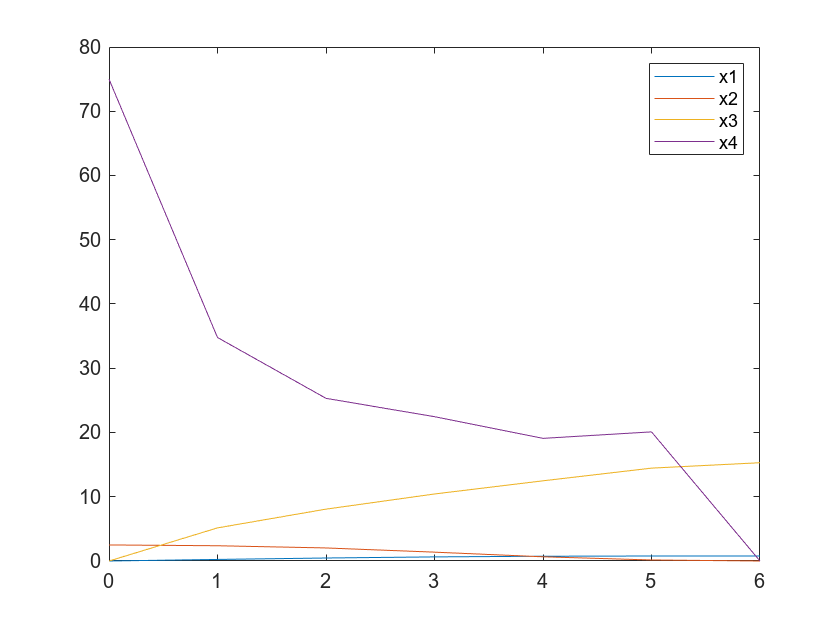

figure()
plot(0:N,xc1(1,:))
hold on 
plot(0:N,xc1(2,:))
hold on 
plot(0:N,xc1(3,:))
hold on 
plot(0:N,xc1(4,:))
hold on 
legend('x1','x2','x3','x4')

y=C*xc1

y =          0  -18.6587   80.5574  150.0000  148.0272   69.8528   24.1733


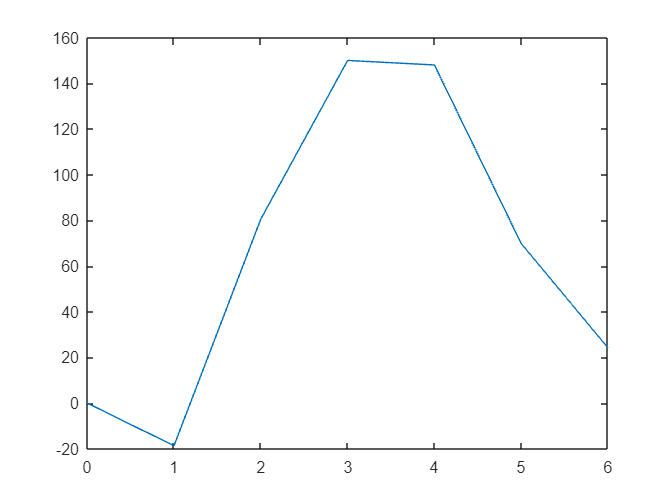

figure()
plot(0:N,y)

%d
model = LTISystem('A', sys_d.A, 'B', sys_d.B,'C',C);
model.u.min = -200;
model.u.max = 200;
u_c=Polyhedron('lb',model.u.min,'ub',model.u.max);
model.x.with('terminalSet');
Tset = Polyhedron('lb',[-10;-0.01;-10;-0.01],'ub',[10;0.01;10;0.01]);
model.x.terminalSet = Tset;
X=Polyhedron('A',[C;-C],'b',[150;150]);  
xd=[];
ud=[];
yd=[];
x0=[0 2.5 0 75]'

x0 =          0
    2.5000
         0
   75.0000


xN=Tset

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities   8 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


k(1)=Tset

Array of 9 polyhedra.


N=0

N = 0

while ~Tset.contains(x0)
    N=N+1
    x_pre=model.reachableSet('X',Tset,'U',u_c,'N',1,'direction','backward');
    Tset=x_pre.intersect(X)
    k(N+1)=Tset
end

N = 1

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities  22 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 2

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities  36 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 3

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities  46 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 4

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities  88 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 5

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 132 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 6

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 156 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 7

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 186 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 8

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 232 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 9 polyhedra.


N = 9

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 284 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 10 polyhedra.


N = 10

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 344 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 11 polyhedra.


N = 11

Polyhedron in R^4 with representations:
    H-rep (redundant)   : Inequalities 360 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Array of 12 polyhedra.


%%%%%%%%%%%%

x0=[0 2.5 0 75]'

x0 =          0
    2.5000
         0
   75.0000


mpc  = MPCController(model, 11);
loop = ClosedLoop(mpc, model);
Nsim=20

Nsim = 20

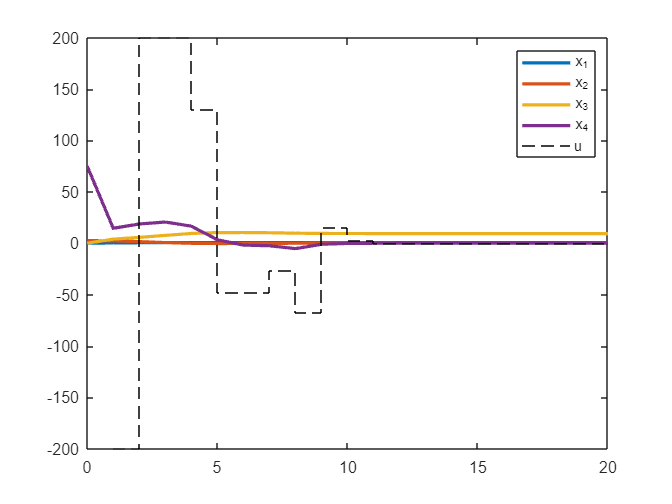

edata = loop.simulate(x0, Nsim);

plot(0:Nsim,edata.X(1,:), 'Linewidth', 2)
hold on
plot(0:Nsim,edata.X(2,:), 'Linewidth', 2)
plot(0:Nsim,edata.X(3,:), 'Linewidth', 2)
plot(0:Nsim,edata.X(4,:), 'Linewidth', 2)
stairs(edata.U, 'k--')
legend({'x_1','x_2','x_3','x_4','u'})

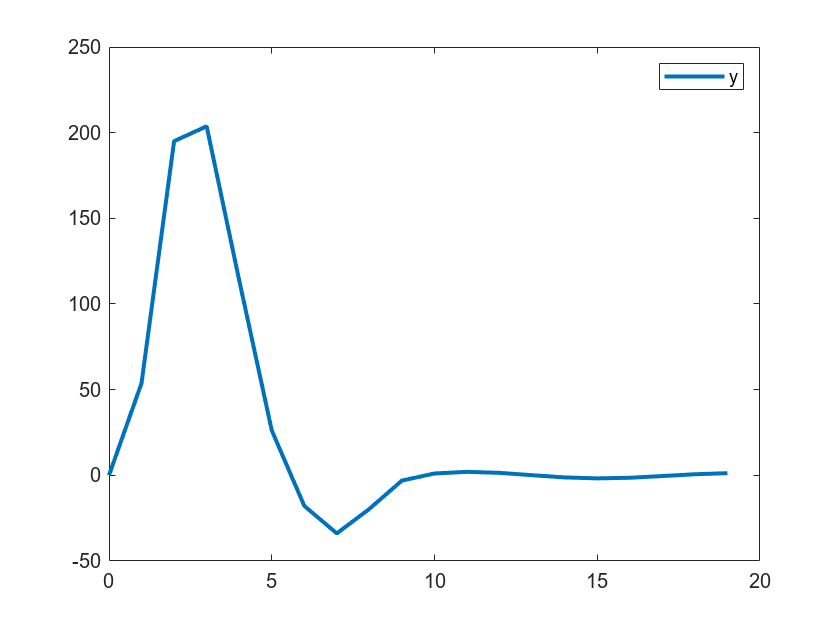

figure()
plot(0:Nsim-1,edata.Y, 'Linewidth', 2)
legend({'y'})

function [x0,x,u,y] =MPC_Controller(Ad,Bd,model,N,x0)    
    mpc = MPCController(model,N);
    [~, ~, data4] = mpc.evaluate(x0);
    x=data4.X(:,1);
    u=data4.U(:,1);
    y=data4.Y(:,1);
    x0=Ad*x+Bd*u;
end
function [kb,Omega,Gamma,Q_bar,R_bar] = MPC_batch(A2,B2,N,Q,R,Pf)
for N=1:N
    n=size(A2,1);%A is nxn, get n
    p=size(B2,2);%B is nxp, get p
    Q_bar = blkdiag(kron(eye(N-1),Q),Pf);
    R_bar = kron(eye(N),R);
    Gamma = zeros(n*N,p*N);
    Omega = zeros(n*N,n);    
    for i=0:N-1
        Gamma = Gamma + kron(diag(ones(N-i,1),-i),A2^i*B2);
        Omega = Omega + [zeros(i*n,n); A2^(i+1); zeros((N-1-i)*n,n)];
    end
    kb=inv(Gamma'*Q_bar*Gamma+R_bar)*Gamma'*Q_bar*Omega;
    kb=kb(1,:);
end
end
